## Parametros

El eje fijo se deja en:

punto_fijo = [0; 0];

El centro del trebol estará ubicado en (se escogió arbitrariamente):

centro_trebol = [25; 25];

 Con esto, necesitamos que los eslabones en máxima estensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2

radio_punto_max = 49.4621

Se escogen como primera aproximación para la longitud de los eslabones:

l_1 = 30;
l_2 = 20;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = l_1+l_2

radio_alcance_max = 50

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max

radio_tolerancia = 0.5379

Se fijan los valores de a y b para que el trebol mida 15cm de lado y esté sin rotar:

a_min = 1.332;
b_no_rot = 4.71;

Para ajustar la escala y orientación del trebol:

escala = 1 % default = 1

escala = 1

rotacion = 0 % en radianes

rotacion = 0

a = a_min * escala;
b = b_no_rot + rotacion;

## Puntas de los eslabones a partir de angulos

syms theta_1;
syms theta_2;

La ubicación de las puntas de los eslabones estará dada por las siguientes expresiones, en donde B es la herramienta de trabajo:

a_x(theta_1) = punto_fijo(1)+l_1*cos(theta_1)

$$a\_x(theta\_1) = 30\,\cos\left(\theta_{1}\right)$$

a_y(theta_1) = punto_fijo(2)+l_1*sin(theta_1)

$$a\_y(theta\_1) = 30\,\sin\left(\theta_{1}\right)$$

b_x(theta_1, theta_2) = a_x+l_2*cos(theta_1+theta_2)

$$b\_x(theta\_1, theta\_2) = 20\,\cos\left(\theta_{1}+\theta_{2}\right)+30\,\cos\left(\theta_{1}\right)$$

b_y(theta_1, theta_2) = a_y+l_2*sin(theta_1+theta_2)

$$b\_y(theta\_1, theta\_2) = 20\,\sin\left(\theta_{1}+\theta_{2}\right)+30\,\sin\left(\theta_{1}\right)$$

## Trebol

El camino que la herramienta de trabajo debe seguir es:

syms theta_trebol;
trebol_x(theta_trebol) = (a*(sin(4*theta_trebol+b)+6)).*cos(theta_trebol)+centro_trebol(1)

$$trebol\_x(theta\_trebol) = \cos\left(\theta_{\mathrm{trebol}}\right)\,\left(\frac{333\,\sin\left(4\,\theta_{\mathrm{trebol}}+\frac{471}{100}\right)}{250}+\frac{999}{125}\right)+25$$

trebol_y(theta_trebol) = (a*(sin(4*theta_trebol+b)+6)).*sin(theta_trebol)+centro_trebol(2)

$$trebol\_y(theta\_trebol) = \sin\left(\theta_{\mathrm{trebol}}\right)\,\left(\frac{333\,\sin\left(4\,\theta_{\mathrm{trebol}}+\frac{471}{100}\right)}{250}+\frac{999}{125}\right)+25$$

## Angulos a partir de posición de B

theta_1_despejado_a_x = finverse(a_x)

$$theta\_1\_despejado\_a\_x(theta\_1) = \mathrm{acos}\left(\frac{\theta_{1}}{30}\right)$$

theta_1_despejado_a_y = finverse(a_y)

$$theta\_1\_despejado\_a\_y(theta\_1) = \mathrm{asin}\left(\frac{\theta_{1}}{30}\right)$$

theta_2_despejado_b_x = finverse(b_x, theta_2)

$$theta\_2\_despejado\_b\_x(theta\_1, theta\_2) = \mathrm{acos}\left(\frac{\theta_{2}}{20}-\frac{3\,\cos\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

theta_2_despejado_b_y = finverse(b_y, theta_2)

$$theta\_2\_despejado\_b\_y(theta\_1, theta\_2) = \mathrm{asin}\left(\frac{\theta_{2}}{20}-\frac{3\,\sin\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

### Rewrite

Para evitar confusiones, voy a reescribir las funciones inversas con un nombre de variables más adecuado. ***ESTÁ HARDCODED, CUIDADO, DEBEN SER IGUALES A LAS DOS DE ARRIBA***:

syms a_x_dado
theta_1_fn_a_x(a_x_dado) = acos(a_x_dado/30)

$$theta\_1\_fn\_a\_x(a\_x\_dado) = \mathrm{acos}\left(\frac{a_{x,\mathrm{dado}}}{30}\right)$$

syms a_y_dado
theta_1_fn_a_y(a_y_dado) = asin(a_y_dado/30)

$$theta\_1\_fn\_a\_y(a\_y\_dado) = \mathrm{asin}\left(\frac{a_{y,\mathrm{dado}}}{30}\right)$$

syms b_x_dado
theta_2_fn_b_x(b_x_dado, theta_1) = acos(b_x_dado/20 - 3*cos(theta_1)/2) - theta_1

$$theta\_2\_fn\_b\_x(b\_x\_dado, theta\_1) = \mathrm{acos}\left(\frac{b_{x,\mathrm{dado}}}{20}-\frac{3\,\cos\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

syms b_y_dado
theta_2_fn_b_y(b_y_dado, theta_1) = asin(b_y_dado/20 - 3*sin(theta_1)/2) - theta_1

$$theta\_2\_fn\_b\_y(b\_y\_dado, theta\_1) = \mathrm{asin}\left(\frac{b_{y,\mathrm{dado}}}{20}-\frac{3\,\sin\left(\theta_{1}\right)}{2}\right)-\theta_{1}$$

## Gráfica

Valores de prueba:

Axd = 0

Axd = 0

Ayd = 30

Ayd = 30

Bxd = 20

Bxd = 20

Byd = 30

Byd = 30

[theta_1_prueba, theta_2_prueba] = get_thetas(Axd, Ayd, Bxd, Byd)

$$theta\_1\_prueba = \frac{\pi }{2}$$

$$theta\_2\_prueba = -\frac{\pi }{2}$$

A = [a_x(theta_1_prueba); a_y(theta_1_prueba)];
B = [b_x(theta_1_prueba, theta_2_prueba); b_y(theta_1_prueba, theta_2_prueba)];

Gráfica:

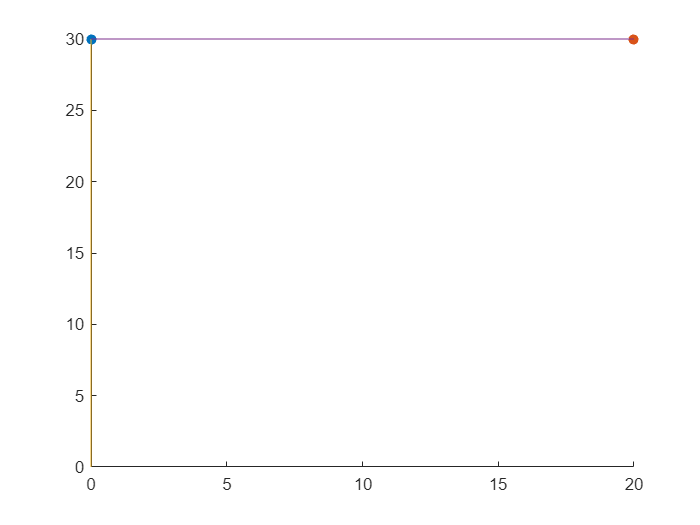

scatter(A(1), A(2), 'filled');
hold on;
scatter(B(1), B(2), 'filled');
plot([punto_fijo(1) A(1)], [punto_fijo(2) A(2)])
plot([A(1) B(1)], [A(2) B(2)])
hold off;

## Helper Functions

function [theta_1, theta_2] = get_thetas(a_x, a_y, b_x, b_y)
    syms theta_1;
    syms a_x_dado;
    theta_1_fn_a_x(a_x_dado) = acos(a_x_dado/30);
    syms a_y_dado;
    theta_1_fn_a_y(a_y_dado) = asin(a_y_dado/30);
    syms b_x_dado;
    theta_2_fn_b_x(b_x_dado, theta_1) = acos(b_x_dado/20 - 3*cos(theta_1)/2) - theta_1;
    syms b_y_dado;
    theta_2_fn_b_y(b_y_dado, theta_1) = asin(b_y_dado/20 - 3*sin(theta_1)/2) - theta_1;
    theta_1_x = theta_1_fn_a_x(a_x);
    theta_1_y = theta_1_fn_a_y(a_y);
    theta_2_x = theta_2_fn_b_x(b_x, theta_1_fn_a_x(a_x));
    theta_2_y = theta_2_fn_b_y(b_y, theta_1_fn_a_y(a_y));
    if theta_1_x == theta_1_y
        theta_1 = theta_1_x;
    end
    if theta_2_x == theta_2_y
        theta_2 = theta_2_x;
    end
end